FILTERING AND DISCRETE-TIME FFT

[x, Fs] = audioread("lamb.wav");
sound(x, Fs);

N = length(x);
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);

X = fft(x);

CONVOLUTION FILTER: 

xSmooth = conv2(x, 0.5, "same")

xSmooth =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


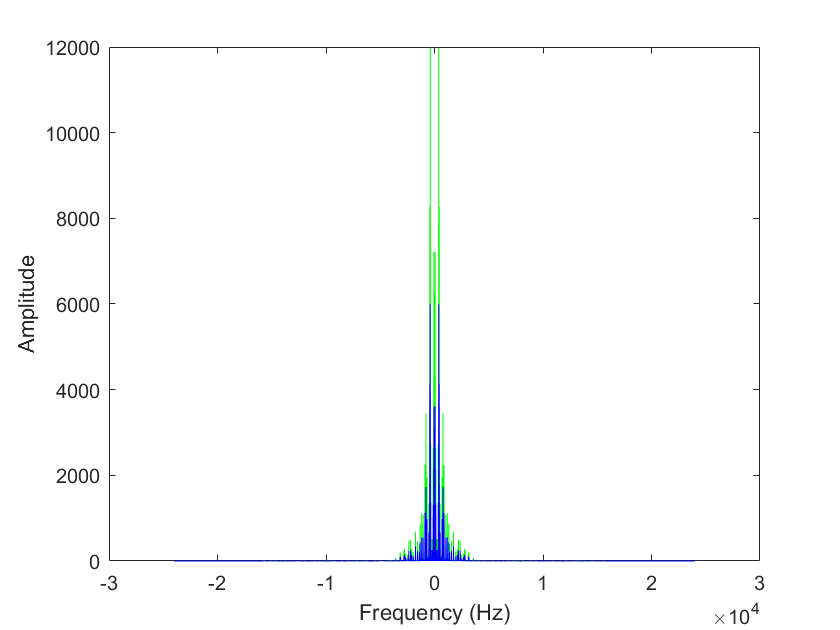

sound(xSmooth, Fs);
XSmooth = fft(xSmooth);

%frequency vs. amplitude of filtered and unfiltered
plot(f,fftshift(abs(X)),'g',f,fftshift(abs(XSmooth)),'b');
xlabel('Frequency (Hz)');
ylabel('Amplitude')

BAND PASS FILTER: 

xBand = bandpass(x,[.01, .999])

xBand =    -0.1254   -0.1254
   -0.1248   -0.1248
   -0.1240   -0.1240
   -0.1232   -0.1232
   -0.1222   -0.1222
   -0.1212   -0.1212
   -0.1200   -0.1200
   -0.1187   -0.1187
   -0.1173   -0.1173
   -0.1157   -0.1157


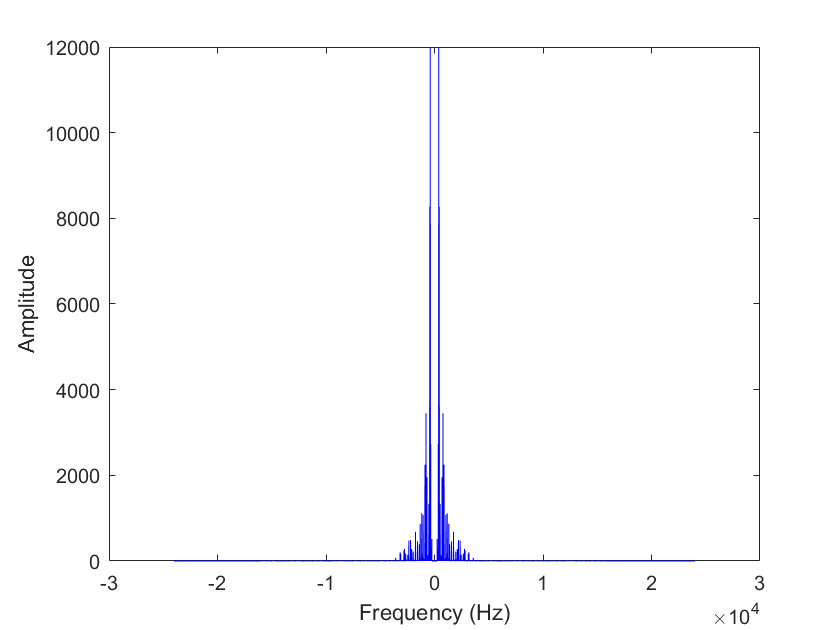

sound(xBand, Fs);
XBand = fft(xBand);

%frequency vs. amplitude of filtered and unfiltered
plot(f,fftshift(abs(XBand)),'b');
xlabel('Frequency (Hz)');
ylabel('Amplitude')

%DTFT
omega = linspace(-pi, (pi*(1-2/N)),N)

omega =    -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1415   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1414   -3.1413   -3.1413   -3.1413   -3.1413   -3.1413


c = fftshift(fft(fftshift(x)))

c = 	1.0e+04 *

   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 - 0.0000i   0.0000 - 0.0000i


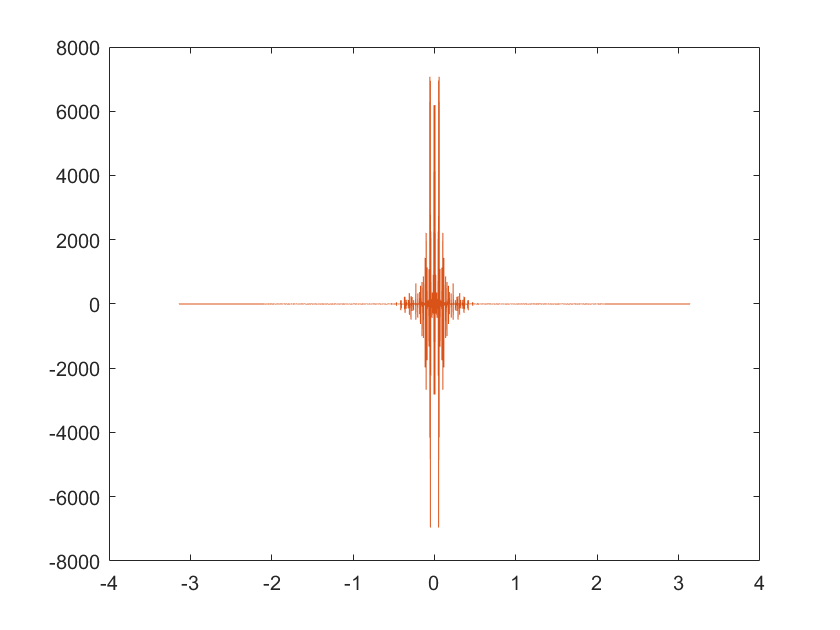

plot(omega, c)

audiowrite("bandpass.wav",xBand,Fs);
audiowrite("convolution.wav",xSmooth,Fs);